### Import the dataset

% "C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv"
path = strcat("C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv")

path = "C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv"

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\Matlab'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\Matlab 



data = readmatrix(path);

### 5a. Visualize Real Data 

%realdata_plot.plot_economic_data();

### Exploratory data analysis (EDA)

% Extract actual data columns
actual_T= data(:,1);       % Time
actual_k = data(:,6);      % Empirical capital
actual_i = data(:,5);      % Empirical investment
actual_c = data(:,9);      % Empirical consumption
actual_g = data(:,5);      % Empirical government spending

% Load simulated data
sim_time = (1:length(sim.ksim))'; % Time index
sim_k = sim.ksim;    % Simulated capital
sim_i = sim.isim;    % Simulated investment
sim_c = sim.csim;    % Simulated consumption
sim_g = sim.gsim;    % Simulated government spending

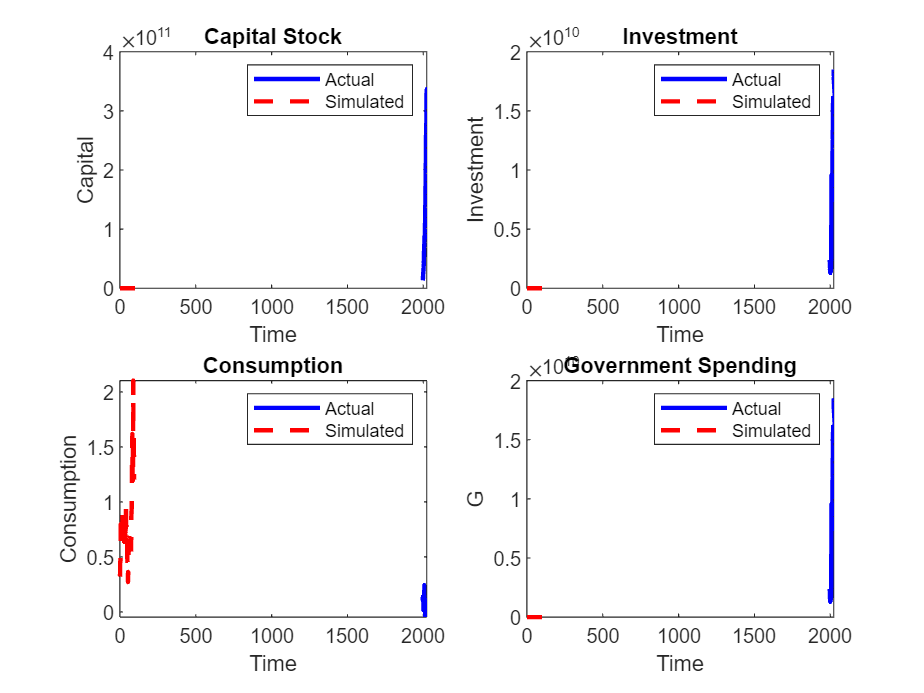

%% Plot Simulated vs Actual Data
figure;

% Capital Stock
subplot(2,2,1);
plot(actual_T, actual_k, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_k, 'r--', 'LineWidth', 2);
title('Capital Stock');
xlabel('Time'); ylabel('Capital');
legend('Actual', 'Simulated');

% Investment
subplot(2,2,2);
plot(actual_T, actual_i, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_i, 'r--', 'LineWidth', 2);
title('Investment');
xlabel('Time'); ylabel('Investment');
legend('Actual', 'Simulated');

% Consumption
subplot(2,2,3);
plot(actual_T, actual_c, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_c, 'r--', 'LineWidth', 2);
title('Consumption');
xlabel('Time'); ylabel('Consumption');
legend('Actual', 'Simulated');

% Government Spending
subplot(2,2,4);
plot(actual_T, actual_g, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_g, 'r--', 'LineWidth', 2);
title('Government Spending');
xlabel('Time'); ylabel('G');
legend('Actual', 'Simulated');

hold off;

%% Parameter Tuning (Modify `par` and Rerun Simulation)
% Example: Adjust discount factor and tax rates to fit actual data
par.beta = 0.95;   % Adjust discount factor
par.tauk = 0.4;    % Adjust capital tax rate
par.taun = 0.25;   % Adjust labor tax rate

% Rerun simulation with new parameters
sim = simulate.grow(par, sol);

% Compare updated results
disp('Simulation updated with new parameters. Re-run the plot to compare again.');

Simulation updated with new parameters. Re-run the plot to compare again.
